# Trabajo práctico: Filtrado digital FIR

## 1) Filtro Moving Average con señales senoidales en MATLAB

### a) Genere una señal senoidal con frecuencia fundamental de 100 Hz. Elija una frecuencia de muestreo adecuada.

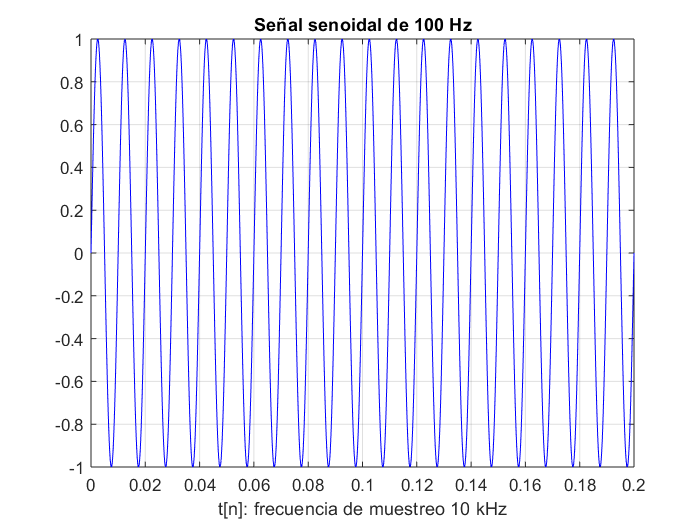

fN = 100; fS = 10e3;

TS = 1 / fS;            % Período de muestreo
t = 0:TS:0.2;

signal = sin(2*pi*fN.*t);

figure(1)
plot(t, signal, '-b');
title("Señal senoidal de 100 Hz");
xlabel("t[n]: frecuencia de muestreo 10 kHz");
grid on;

### b) Agregue ruido gaussiano a la señal senoidal tal que la relación señal-ruido entre la señal senoidal y la señal con ruido sea de 15 dB.

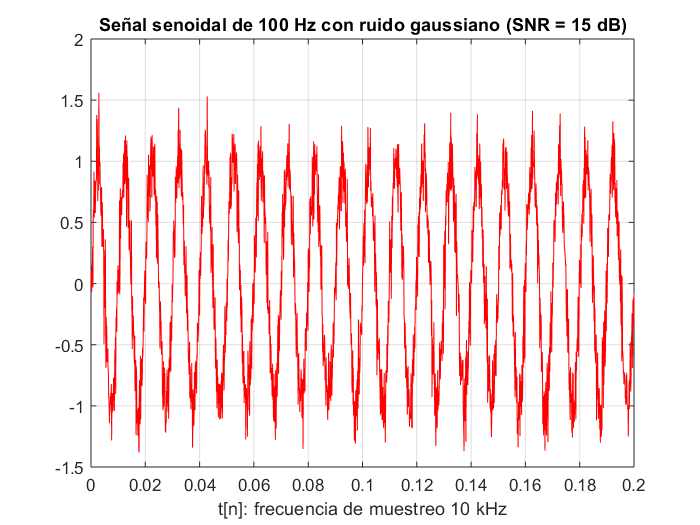

snr = 15;
signal_n = awgn(signal, snr);

figure(2)
plot(t, signal_n, '-r');
title("Señal senoidal de 100 Hz con ruido gaussiano (SNR = 15 dB)");
xlabel("t[n]: frecuencia de muestreo 10 kHz");
grid on;

### c) Calcule el valor máximo del orden del filtro (N_max). Determine las frecuencias fs y fco.


$$N_{max} = \text{round}\left( \sqrt{\frac{0.885894^{2}\cdot f_{s}^{2}}{f_{CO}^{2}} - 1} \right)$$


fco = fN;
N_max = round(sqrt(0.885894^2*fS^2/fco^2 - 1));
disp("Nmax = " + N_max);

Nmax = 89


### d) Aplique filtrado del tipo moving average a la señal con ruido para un filtro MA con dimensión igual N = N_max. Utilice la función filter.

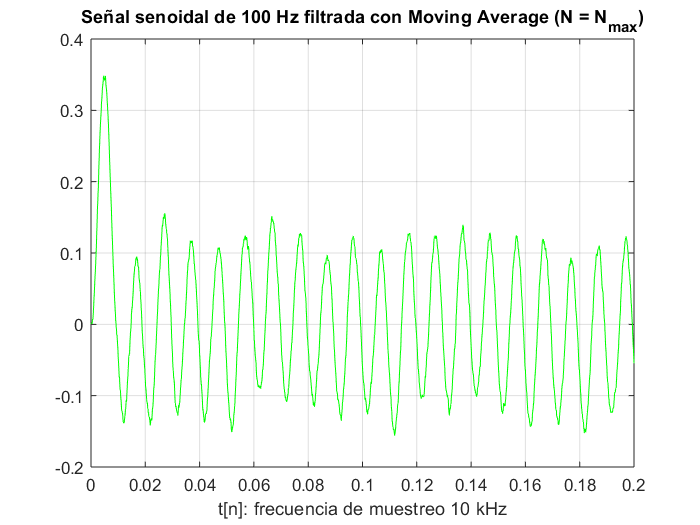

N = N_max;
kernel = ones(1, N) / N;
signal_f = filter(kernel, 1, signal_n);

figure(3)
plot(t, signal_f, '-g');
title("Señal senoidal de 100 Hz filtrada con Moving Average (N = N_{max})");
xlabel("t[n]: frecuencia de muestreo 10 kHz");
grid on;

### e) Grafique la respuesta en frecuencia y fase del filtro MA. Use la función freqz.

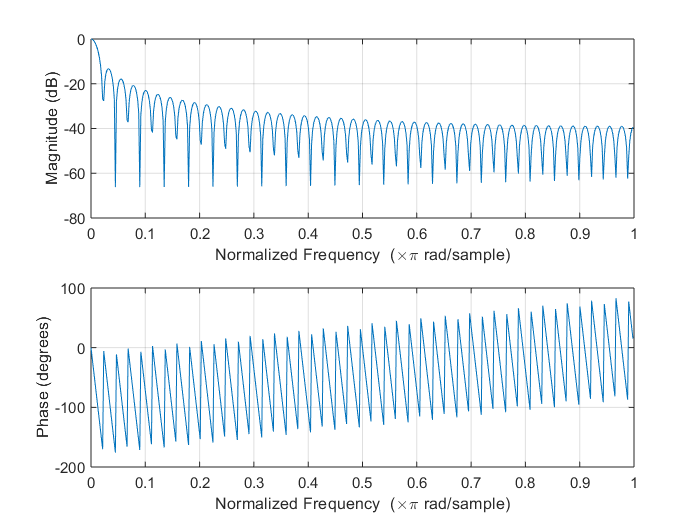

freqz(kernel, 1);

### f) Grefique las señales en el dominio del tiempo sin ruido, con ruido y filtrada, y compare las tres.

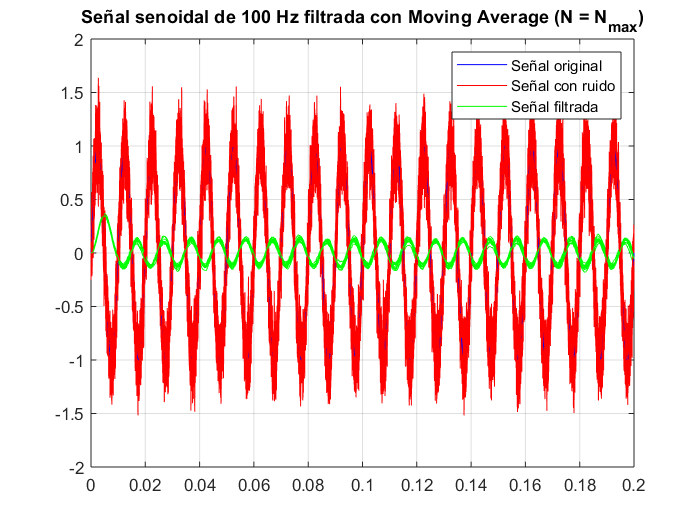

figure(4)
plot(t, signal, '-b');
grid on;
hold on;

plot(t, signal_n, '-r');

plot(t, signal_f, '-g');
legend("Señal original", "Señal con ruido", "Señal filtrada");

### g) Grafique la respuesta en frecuencia de las señales original y filtrada y compare. Utilice la función provista my_dft.

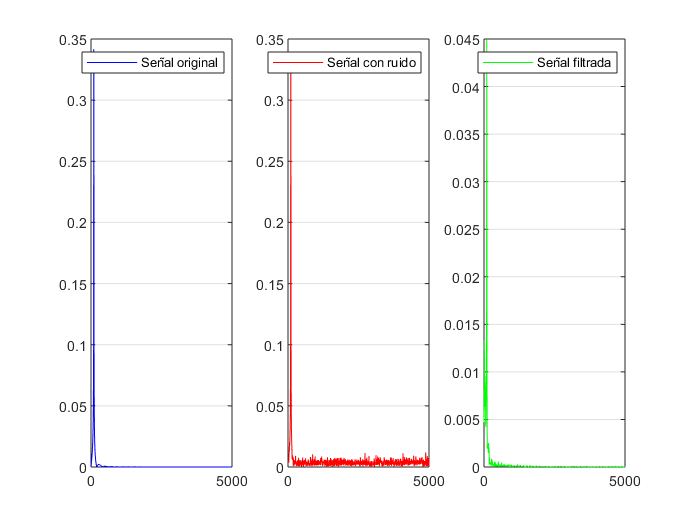

[f, dft_mag, dft_phase, dft, NFFT] = my_dft([signal; signal_n; signal_f], fS);

figure(5)
subplot(1, 3, 1);
plot(f, dft_mag(:,1), '-b');
legend("Señal original");
grid on;

subplot(1, 3, 2);
plot(f, dft_mag(:,2), '-r');
legend("Señal con ruido");
grid on;

subplot(1, 3, 3);
plot(f, dft_mag(:,3), '-g');
legend("Señal filtrada");
grid on;

### h) Repita los puntos d) a g) para N = N_max / 2 y N = N_max * 10